%Bubble exercise
bubbleImage = rgb2gray(imread('bubbles.png'))

bubbleImage = 272×279 uint8 matrix
   234   238   237   237   237   239   239   239   239   239   238   237   237   237   237   238   244   250   247   243   247   251   252   245   236   233   237   237   237   241   249   250   247   244   241   237   238   238   238   237   236   237   237   238   238   238   238   237   237   237
   143   138   135   143   146   145   148   148   147   146   142   140   140   140   139   137   183   219   198   176   213   241   235   183   154   136   131   130   148   176   212   222   215   191   159   140   137   137   138   138   139   140   140   140   140   140   140   140   140   140
   136   138   137   142   145   147   149   149   148   146   140   139   139   139   137   132   179   219   210   176   211   236   227   188   154   133   129   143   153   177   213   220   218   192   154   138   136   135   135   136   137   137   137   137   136   136   137   138   138   138
   136   140   141   140   142   147   148   149   148   145  

t = graythresh(bubbleImage)

t = 0.6627

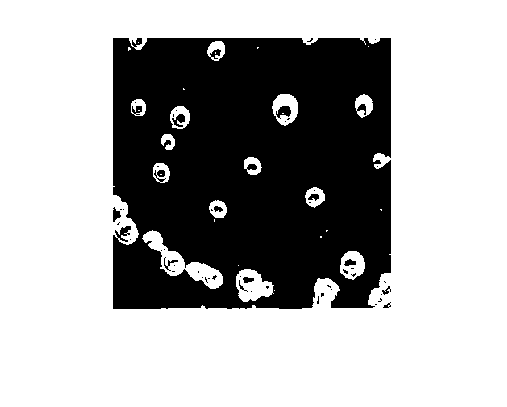

imThresh = imbinarize(bubbleImage,t);
figure()
title('Imagen thresholding')
imshow(imThresh)
axis off

imwrite(imThresh,'segmented_bubbles.png')

imFilled = imfill(imThresh,'holes')

imFilled = 272×279 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   

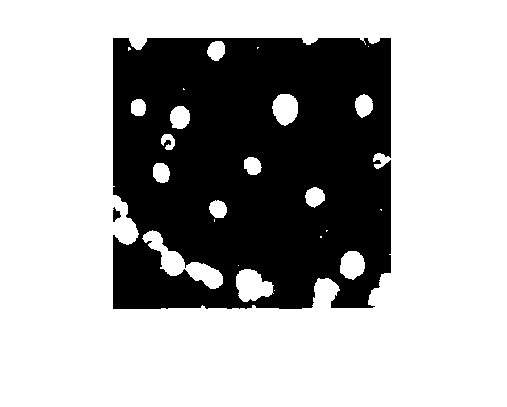


figure()
title('Llenado de burbujas')
imshow(imFilled)
axis off

imwrite(imFilled,'filled_bubbles.png')

comps = bwconncomp(imFilled);
cutImage1  = zeros(size(imFilled));
cutImage1(comps.PixelIdxList{6}) = 1;
cutImage2 = zeros(size(imFilled));
cutImage2(comps.PixelIdxList{8}) = 1;
cutImage3 = zeros(size(imFilled));
cutImage3(comps.PixelIdxList{9}) = 1

cutImage3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

cutImage4 = zeros(size(imFilled));
cutImage4(comps.PixelIdxList{12}) = 1

cutImage4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

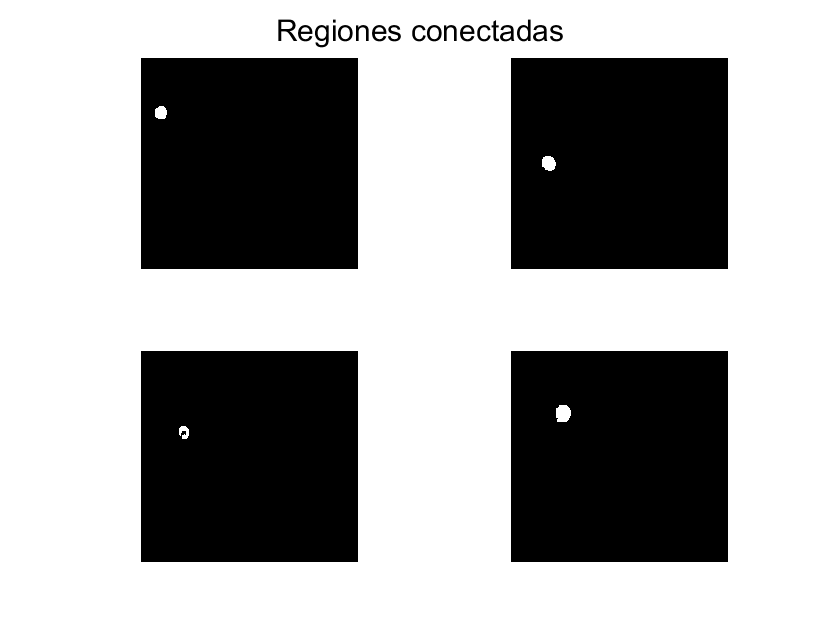

figure()
sgtitle('Regiones conectadas')
hold on 
subplot(2,2,1)
imshow(cutImage1)
subplot(2,2,2)
imshow(cutImage2)
subplot(2,2,3)
imshow(cutImage3)
subplot(2,2,4)
imshow(cutImage4)
hold off
axis off

bubbleArea = 0;
for i = 1:length(comps.PixelIdxList)
    region = comps.PixelIdxList{i};
    bubbleArea = bubbleArea + length(region);
end

totalArea = size(bubbleImage,1)*size(bubbleImage,2);


h = figure()

h =   Figure (55) with properties:

      Number: 55
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 438 560 420]
       Units: 'pixels'

  Show all properties


imshow(imFilled)
[centers, radii, metric] = imfindcircles(imFilled,[5 100]);

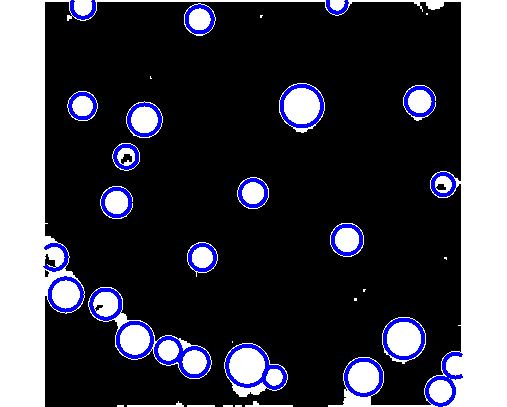

viscircles(centers, radii,'EdgeColor','b');
axis off
set(gca, 'unit', 'normalize')
set(gca, 'position', [0 0 1 1]);
saveas(gca,'mask22.jpg');